colors = ...
 1/256*[ 31,119,180; % 1 默认蓝色
        255,127,14;  % 2 橘色
         44,160,44;  % 3 绿色
        214,39,40;   % 4 红色
        148,103,189; % 5 紫色
        140,86,75;   % 6 棕色 
       227,119,194;  % 7 粉色
       127,127,127;  % 8 灰色
       188,189,34;   % 9 青棕
       23,190,207;   % 10 淡蓝
       26,85,255;    % 11 鲜蓝色
       ];
figure(1)
p = plot(position_0(:,2),position_0(:,1), ...
    position_9(:,2),position_9(:,1), ...
    position_39(:,2),position_39(:,1), ...
    position_59(:,2),position_59(:,1), ...
    position_79(:,2),position_79(:,1),...
    position_99(:,2),position_99(:,1), ...
    position_99_static_users(:,2),position_99_static_users(:,1), ...
    static_trajectoty_y, static_trajectoty_x,'--',...
    user_0_trajectory_y,user_0_trajectory_x,'--', ...
    user_1_trajectory_y,user_1_trajectory_x,'--')

p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


for i = 1:6
    p(i).LineWidth = 0.5+(i-1)/6 *0.5
end

p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


p(6).Color = 'r'

p =   10×1 Line 数组:

  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line
  Line


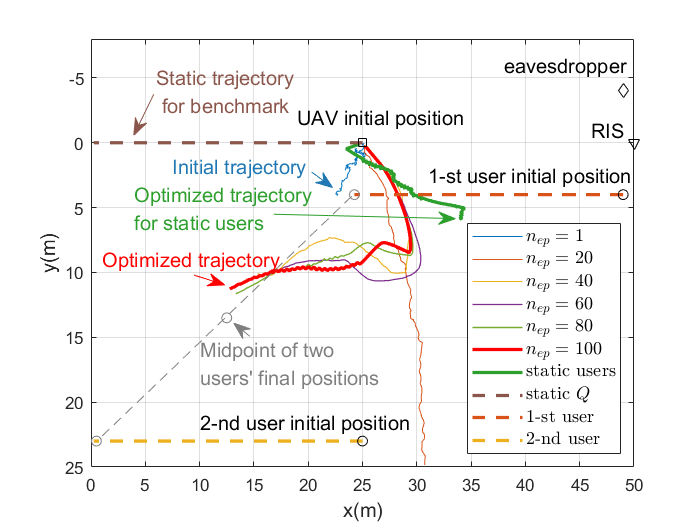

p(6).LineWidth = 2;
p(7).LineWidth = 2;
p(7).Color = colors(3,:);
p(8).LineWidth = 2;
p(8).Color = colors(6,:);
p(9).LineWidth = 2;
p(10).LineWidth = 2;
annotation('arrow',[0.2197 0.1911],[0.8205 0.7424],"Color",colors(6,:))
text(6,-4,{"Static trajectory";" for benchmark"},"Color",colors(6,:), "FontSize",12)


hold on
plot(25,0,'s','Color','K')
text(19,-2,'UAV initial position', "FontSize",12)
plot(50,0,'v','Color','K')
text(46,-1,'RIS', "FontSize",12)

plot(49,4,'o','Color','K')
text(31,2.5,'1-st user initial position', "FontSize",12)
hold on
plot(25,23,'o','Color','K')
text(10,21.5,'2-nd user initial position', "FontSize",12)

plot(49,-4,'d','Color','K')
text(38,-6,'eavesdropper', "FontSize",12)

plot(0.5,23,'o','Color',colors(8,:))
plot(24.25,4,'o','Color',colors(8,:))
plot(12.5,13.5,'o','Color',colors(8,:))
annotation('line',[0.5025 0.1397],[0.6262 0.1614],"Color",[colors(8,:)],"LineStyle","--")
annotation('textarrow',[0.3568 0.334],[0.3595 0.3843],"Color",[colors(8,:)])
text(10,17,{"Midpoint of two ";"users' final positions"},"Color",[colors(8,:)], "FontSize",12)

annotation('arrow','X',[0.4451 0.475],'Y',[0.6726 0.6428],"Color",[colors(1,:)])
text(7.5,1.8,"Initial trajectory","Color",[colors(1,:)], "FontSize",12)

text(1,9,"Optimized trajectory","Color",'r', "FontSize",12)

annotation('arrow','X',[0.2774 0.321],'Y',[0.4759 0.4574],"Color",'r')
annotation('arrow','X',[0.391 0.6504],'Y',[0.5919 0.5836],'Color',[colors(3,:)])
text(4,5,{"Optimized trajectory";"for static users"},"Color",[colors(3,:)], "FontSize",12)

ylim([-8 25]) 
set(gca,'YDir','reverse')
legend('$n_{ep}=1$', '$n_{ep}=20$','$n_{ep}=40$','$n_{ep}=60$','$n_{ep}=80$','$n_{ep}=100$', ...
    'static users',...
    'static $Q$',...
    '1-st user',...
    '2-nd user',...
    'interpreter','latex',...
    'Location','southeast', ...
    'FontSize',11)
xlim([0 50])
xlabel('x(m)','FontSize',12)
ylabel('y(m)','FontSize',12)
grid on